# P16 Cx26 ABRs

defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\ABRs'

defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\ABRs'

% also 2 P15 animals, too
cd(defaultDir);

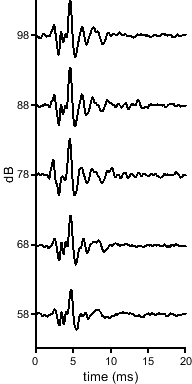


% load representative ABR click traces, plot 

addpath('cjk-2019_10_08-P16_abr_cx26flfl_3');
flflCAP ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006};
figure
hold on
for x = 1:length(flflCAP)
    plot(flflCAP{1,x}.AverageData(:,1),flflCAP{1,x}.AverageData(:,4)-10*(x-1),'k','LineWidth',1.5)
end
dim = [2,4];
yticks([-40 -30 -20 -10 0]);
yticklabels([58 68 78 88 98])
xlim([0 20]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);

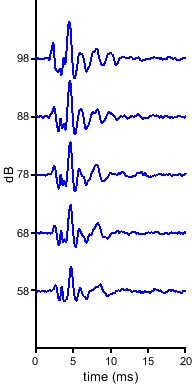


rmpath('cjk-2019_10_08-P16_abr_cx26flfl_3');


addpath('cjk-2019_09_12-P16_abr_tectacx26fl_6');
tectaCAP ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006};
figure
hold on
for x = 1:length(tectaCAP)
    plot(tectaCAP{1,x}.AverageData(:,1),tectaCAP{1,x}.AverageData(:,4)-10*(x-1),'b','LineWidth',1.5)
end
dim = [2,4];
yticks([-40 -30 -20 -10 0]);
yticklabels([58 68 78 88 98])
xlim([0 20]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);

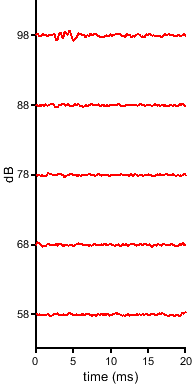


rmpath('cjk-2019_09_12-P16_abr_tectacx26fl_6');

addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
tectaflCAP ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006};
figure
hold on
for x = 1:length(tectaflCAP)
    plot(tectaflCAP{1,x}.AverageData(:,1),tectaflCAP{1,x}.AverageData(:,4)-10*(x-1),'r', 'LineWidth',1.5)
end
dim = [2,4];
yticks([ -40 -30 -20 -10 0]);
yticklabels([58 68 78 88 98])
xlim([0 20]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);

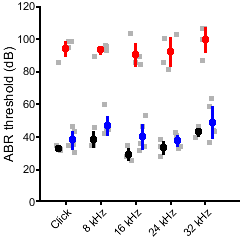

% Plot thresholds (currently in lab notebook), determine how to automate

tectaflclickp21 = [85.7,98,94.5,98.1];
tectafl8p21 = [89.2,95.9,92.5,95.5];
tectafl16p21 = [83.9,89.0,85.5,103];
tectafl24p21 = [80.9,100.0,85.6,102.4];
tectafl32p21 = [86.5,106,99.2,106];

tectaclickp21 = [35.1,34.8,30.3,46.5,43.1];
tecta8p21 = [45.3,42.7,42.2,59.4,44.5];
tecta16p21 = [35.9,34.0,31.8,52.8,46.4];
tecta24p21 = [32.8,34.2,42.4,37.8,40.5];
tecta32p21 = [43.7,43.0,36.4,58.3,63.1];

flflclickp21 = [31.3,31.9,34.3];
flfl8p21 = [34.6,34.7,45.8];
flfl16p21 = [34.5,28.1,25.5];
flfl24p21 = [38.3,27.7,34.1];
flfl32p21 = [39.2,43.5,46.0];

% plot all on one graph
figure
hold on
conditions = {'Click','8 kHz','16 kHz','24 kHz','32 kHz'};
ylbl = 'ABR threshold (dB)';
dim = [2.5 2.5];
markSz = [20 20];
color1 = 'k';
color2 = 'r';
color3 = 'b';
compare5offsetM(flflclickp21,flfl8p21,flfl16p21,flfl24p21,flfl32p21,conditions,ylbl,dim,markSz,color1,color2)
compare5(tectaflclickp21,tectafl8p21,tectafl16p21,tectafl24p21,tectafl32p21,conditions,ylbl,dim,markSz,color2,color1)
compare5offsetP(tectaclickp21,tecta8p21,tecta16p21,tecta24p21,tecta32p21,conditions,ylbl,dim,markSz,color3,color1)
ylim([0 120])


genobase = {'con','con','con','cre','cre','cre','cre','cre','cko','cko','cko','cko',};
geno = [genobase,genobase,genobase,genobase,genobase]';
mousebase = [1 2 3 4 5 6 7 8 9 10 11 12];
mouse = [mousebase,mousebase,mousebase,mousebase,mousebase]';
location = {'clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','clk','8','8','8','8','8','8','8','8','8','8','8','8','16','16','16','16','16','16','16','16','16','16','16','16','24','24','24','24','24','24','24','24','24','24','24','24','32','32','32','32','32','32','32','32','32','32','32','32'}'; 
thresH = [flflclickp21(:)',tectaclickp21(:)',tectaflclickp21(:)',flfl8p21(:)',tecta8p21(:)',tectafl8p21(:)',flfl16p21(:)',tecta16p21(:)',tectafl16p21(:)',flfl24p21(:)',tecta24p21(:)',tectafl24p21(:)',flfl32p21(:)',tecta32p21(:)',tectafl32p21(:)',]';

tbl = table(geno,mouse,location,thresH,'VariableNames',{'Genotype','Mouse','Location','thresh'})

tbl = 60×4 table
    Genotype    Mouse    Location    thresh
    ________    _____    ________    ______

    {'con'}       1      {'clk'}      31.3 
    {'con'}       2      {'clk'}      31.9 
    {'con'}       3      {'clk'}      34.3 
    {'cre'}       4      {'clk'}      35.1 
    {'cre'}       5      {'clk'}      34.8 
    {'cre'}       6      {'clk'}      30.3 
    {'cre'}       7      {'clk'}      46.5 
    {'cre'}       8      {'clk'}      43.1 
    {'cko'}       9      {'clk'}      85.7 
    {'cko'}      10      {'clk'}        98 
    {'cko'}      11      {'clk'}      94.5 
    {'cko'}      12      {'clk'}      98.1 
    {'con'}       1      {'8'  }      34.6 
    {'con'}       2      {'8'  }      34.7 
    {'con'}       3      {'8'  }      45.8 
    {'cre'}       4      {'8'  }      45.3 


lme = fitlme(tbl,'thresh~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations              60
    Fixed effects coefficients           3
    Random effects coefficients         17
    Covariance parameters                3

Formula:
    thresh ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    387.98    400.24    -187.99          375.98  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat     DF    pValue        Lower      Upper 
    {'(Intercept)' }         35.3       3.9251    8.9935    57    1.5824e-12      27.44     43.16
    {'Genotype_cre'}         6.98       4.3794    1.5938    57       0.11651    -1.7897     15.75
    {'Genotype_cko'}        58.57       4.5801    12.788    57    2.1785e-18     49.398    67.742

Random effects covariance parameters (95% CIs):<

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =    35.3000
    6.9800
   58.5700


betanames = 3×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cre'}
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat     DF        pValue        Lower     Upper 
    {'(Intercept)' }         35.3       3.9251    8.9935    12.131    1.0257e-06    26.758    43.842
    {'Genotype_cre'}         6.98       4.3794    1.5938         9       0.14544    -2.927    16.887
    {'Genotype_cko'}        58.57       4.5801    12.788         9    4.4717e-07    48.209    68.931



genobase = {'cre','cre','cre','cre','cre','cko','cko','cko','cko'};
geno = [genobase,genobase,genobase,genobase,genobase]';
mousebase = [1 2 3 4 5 6 7 8 9];
mouse = [mousebase,mousebase,mousebase,mousebase,mousebase]';
location = {'clk','clk','clk','clk','clk','clk','clk','clk','clk','8','8','8','8','8','8','8','8','8','16','16','16','16','16','16','16','16','16','24','24','24','24','24','24','24','24','24','32','32','32','32','32','32','32','32','32',}'; 
thresH = [tectaclickp21(:)',tectaflclickp21(:)',tecta8p21(:)',tectafl8p21(:)',tecta16p21(:)',tectafl16p21(:)',tecta24p21(:)',tectafl24p21(:)',tecta32p21(:)',tectafl32p21(:)',]';
tbl = table(geno,mouse,location,thresH,'VariableNames',{'Genotype','Mouse','Location','thresh'})

tbl = 45×4 table
    Genotype    Mouse    Location    thresh
    ________    _____    ________    ______

    {'cre'}       1      {'clk'}      35.1 
    {'cre'}       2      {'clk'}      34.8 
    {'cre'}       3      {'clk'}      30.3 
    {'cre'}       4      {'clk'}      46.5 
    {'cre'}       5      {'clk'}      43.1 
    {'cko'}       6      {'clk'}      85.7 
    {'cko'}       7      {'clk'}        98 
    {'cko'}       8      {'clk'}      94.5 
    {'cko'}       9      {'clk'}      98.1 
    {'cre'}       1      {'8'  }      45.3 
    {'cre'}       2      {'8'  }      42.7 
    {'cre'}       3      {'8'  }      42.2 
    {'cre'}       4      {'8'  }      59.4 
    {'cre'}       5      {'8'  }      44.5 
    {'cko'}       6      {'8'  }      89.2 
    {'cko'}       7      {'8'  }      95.9 


lme = fitlme(tbl,'thresh~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations              45
    Fixed effects coefficients           2
    Random effects coefficients         14
    Covariance parameters                3

Formula:
    thresh ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    298.46    307.27    -144.23          288.46  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE       tStat     DF    pValue        Lower     Upper 
    {'(Intercept)' }        42.28       3.439    12.294    43     1.146e-15    35.345    49.215
    {'Genotype_cko'}        51.59       4.505    11.452    43    1.2056e-14    42.505    60.675

Random effects covariance parameters (95% CIs):
Group: Location (5 Levels)
    Name1                  Name2                  Type           Est

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =    42.2800
   51.5900


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE       tStat     DF        pValue        Lower     Upper 
    {'(Intercept)' }        42.28       3.439    12.294    9.6893    3.1468e-07    34.584    49.976
    {'Genotype_cko'}        51.59       4.505    11.452         7    8.6968e-06    40.937    62.243







group1 = [flflclickp21 NaN NaN];
group3 = [tectaflclickp21, NaN];
group2 = [tectaclickp21];

 h1 = kstest(group1);
        h2 = kstest(group2);
        h3 = kstest(group3);
        
        
        if h1 == 1 || h2 == 1 || h3 == 1
            disp('not normal')
            [p,~,stats] = kruskalwallis([group1' group2' group3'],{'Tecta-cre','Cx26 fl/fl', 'Tecta-cre;Cx26fl/fl'},'off')
            [c,~,~,gnames] = multcompare(stats,'display','off')
        else 
       [p,~,stats] = anova1([group1' group2' group3'],{'WT','Alpha9 KO','Alpha9 GOF'},'off')
       [c,~,~,gnames] = multcompare(stats,'display','off')
        end

not normal


p = 0.0164

stats = struct with fields:
       gnames: {3×1 cell}
            n: [3 5 4]
       source: 'kruskalwallis'
    meanranks: [3 5.4000 10.5000]
         sumt: 0


c =     1.0000    2.0000   -8.5713   -2.4000    3.7713    0.6330
    1.0000    3.0000  -13.9540   -7.5000   -1.0460    0.0177
    2.0000    3.0000  -10.7687   -5.1000    0.5687    0.0881


gnames = 3×1 cell array
    {'Tecta-cre'          }
    {'Cx26 fl/fl'         }
    {'Tecta-cre;Cx26fl/fl'}


        
        group1 = [flfl8p21 NaN NaN];
group3 = [tectafl8p21 NaN];
group2 = [tecta8p21];

 h1 = kstest(group1);
        h2 = kstest(group2);
        h3 = kstest(group3);
        
        
        if h1 == 1 || h2 == 1 || h3 == 1
            disp('not normal')
            [p,~,stats] = kruskalwallis([group1' group2' group3'],{'Tecta-cre','Cx26 fl/fl', 'Tecta-cre;Cx26fl/fl'},'off')
            [c,~,~,gnames] = multcompare(stats,'display','off')
        else 
       [p,~,stats] = anova1([group1' group2' group3'],{'WT','Alpha9 KO','Alpha9 GOF'},'off')
       [c,~,~,gnames] = multcompare(stats,'display','off')
        end

not normal


p = 0.0194

stats = struct with fields:
       gnames: {3×1 cell}
            n: [3 5 4]
       source: 'kruskalwallis'
    meanranks: [3.3333 5.2000 10.5000]
         sumt: 0


c =     1.0000    2.0000   -8.0379   -1.8667    4.3046    0.7582
    1.0000    3.0000  -13.6207   -7.1667   -0.7126    0.0251
    2.0000    3.0000  -10.9687   -5.3000    0.3687    0.0726


gnames = 3×1 cell array
    {'Tecta-cre'          }
    {'Cx26 fl/fl'         }
    {'Tecta-cre;Cx26fl/fl'}


        
              group1 = [flfl16p21 NaN NaN];
group3 = [tectafl16p21 NaN];
group2 = [tecta16p21];

 h1 = kstest(group1);
        h2 = kstest(group2);
        h3 = kstest(group3);
        
        
        if h1 == 1 || h2 == 1 || h3 == 1
            disp('not normal')
            [p,~,stats] = kruskalwallis([group1' group2' group3'],{'Tecta-cre','Cx26 fl/fl', 'Tecta-cre;Cx26fl/fl'},'off')
            [c,~,~,gnames] = multcompare(stats,'display','off')
        else 
       [p,~,stats] = anova1([group1' group2' group3'],{'WT','Alpha9 KO','Alpha9 GOF'},'off')
       [c,~,~,gnames] = multcompare(stats,'display','off')
        end

not normal


p = 0.0134

stats = struct with fields:
       gnames: {3×1 cell}
            n: [3 5 4]
       source: 'kruskalwallis'
    meanranks: [2.6667 5.6000 10.5000]
         sumt: 0


c =     1.0000    2.0000   -9.1046   -2.9333    3.2379    0.5054
    1.0000    3.0000  -14.2874   -7.8333   -1.3793    0.0124
    2.0000    3.0000  -10.5687   -4.9000    0.7687    0.1060


gnames = 3×1 cell array
    {'Tecta-cre'          }
    {'Cx26 fl/fl'         }
    {'Tecta-cre;Cx26fl/fl'}


        
         group1 = [flfl24p21 NaN NaN];
group3 = [tectafl24p21 NaN];
group2 = [tecta24p21];

 h1 = kstest(group1);
        h2 = kstest(group2);
        h3 = kstest(group3);
        
        
        if h1 == 1 || h2 == 1 || h3 == 1
            disp('not normal')
            [p,~,stats] = kruskalwallis([group1' group2' group3'],{'Tecta-cre','Cx26 fl/fl', 'Tecta-cre;Cx26fl/fl'},'off')
            [c,~,~,gnames] = multcompare(stats,'display','off')
        else 
       [p,~,stats] = anova1([group1' group2' group3'],{'WT','Alpha9 KO','Alpha9 GOF'},'off')
       [c,~,~,gnames] = multcompare(stats,'display','off')
        end

not normal


p = 0.0194

stats = struct with fields:
       gnames: {3×1 cell}
            n: [3 5 4]
       source: 'kruskalwallis'
    meanranks: [3.3333 5.2000 10.5000]
         sumt: 0


c =     1.0000    2.0000   -8.0379   -1.8667    4.3046    0.7582
    1.0000    3.0000  -13.6207   -7.1667   -0.7126    0.0251
    2.0000    3.0000  -10.9687   -5.3000    0.3687    0.0726


gnames = 3×1 cell array
    {'Tecta-cre'          }
    {'Cx26 fl/fl'         }
    {'Tecta-cre;Cx26fl/fl'}


        
        group1 = [flfl32p21 NaN NaN];
group3 = [tectafl32p21 NaN];
group2 = [tecta32p21];

 h1 = kstest(group1);
        h2 = kstest(group2);
        h3 = kstest(group3);
        
        
        if h1 == 1 || h2 == 1 || h3 == 1
            disp('not normal')
            [p,~,stats] = kruskalwallis([group1' group2' group3'],{'Tecta-cre','Cx26 fl/fl', 'Tecta-cre;Cx26fl/fl'},'off')
            [c,~,~,gnames] = multcompare(stats,'display','off')
        else 
       [p,~,stats] = anova1([group1' group2' group3'],{'WT','Alpha9 KO','Alpha9 GOF'},'off')
       [c,~,~,gnames] = multcompare(stats,'display','off')
        end

not normal


p = 0.0235

stats = struct with fields:
       gnames: {3×1 cell}
            n: [3 5 4]
       source: 'kruskalwallis'
    meanranks: [4 4.8000 10.5000]
         sumt: 6


c =     1.0000    2.0000   -6.9605   -0.8000    5.3605    0.9502
    1.0000    3.0000  -12.9428   -6.5000   -0.0572    0.0474
    2.0000    3.0000  -11.3587   -5.7000   -0.0413    0.0479


gnames = 3×1 cell array
    {'Tecta-cre'          }
    {'Cx26 fl/fl'         }
    {'Tecta-cre;Cx26fl/fl'}


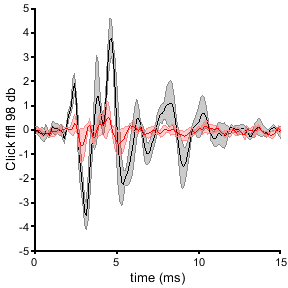

% mean traces

%Cx26 flfl 
% click averages, 0 dB atten (98 dB) 
clickflfl ={1,2,3};
addpath('cjk-2019_09_12-P16_abr_cx26flfl_1');
clickflfl{1,1} = EPavg_p003;
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_1')
addpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
clickflfl{1,2} = EPavg_p003;
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
addpath('cjk-2019_10_08-P16_abr_cx26flfl_3');
clickflfl{1,3} = EPavg_p003;
rmpath('cjk-2019_10_08-P16_abr_cx26flfl_3');

meanClickflfl = mean([(clickflfl{1,1}.AverageData(:,4))';(clickflfl{1,2}.AverageData(:,4))';(clickflfl{1,3}.AverageData(:,4))'],1);

stdClickflfl = std([(clickflfl{1,1}.AverageData(:,4))';(clickflfl{1,2}.AverageData(:,4))';(clickflfl{1,3}.AverageData(:,4))'],1);
figure
%plot(clickflfl{1,1}.AverageData(:,1)',meanClickflfl,'k','LineWidth',2)
hold on
shadedErrorBar(clickflfl{1,1}.AverageData(:,1)',meanClickflfl,stdClickflfl) 
clickcko ={1,2,3,4};
addpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3');
clickcko{1,1} = EPavg_p003;
rmpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3')
addpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
clickcko{1,2} = EPavg_p003;
rmpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
clickcko{1,3} = EPavg_p003;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
clickcko{1,4} = EPavg_p003;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');

meanClickcko = mean([(clickcko{1,1}.AverageData(:,4))';(clickcko{1,2}.AverageData(:,4))';(clickcko{1,3}.AverageData(:,4))';(clickcko{1,4}.AverageData(:,4))'],1);
stdClickcko=std([(clickcko{1,1}.AverageData(:,4))';(clickcko{1,2}.AverageData(:,4))';(clickcko{1,3}.AverageData(:,4))';(clickcko{1,4}.AverageData(:,4))'],1);
%plot(clickcko{1,1}.AverageData(:,1)',meanClickcko,'r','LineWidth',2)
shadedErrorBar(clickcko{1,1}.AverageData(:,1)',meanClickcko,stdClickcko,'lineprops','r')

dim = [3 3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('Click flfl 98 db');
handle = gcf;
figQuality(gcf,gca,dim);
hold off 

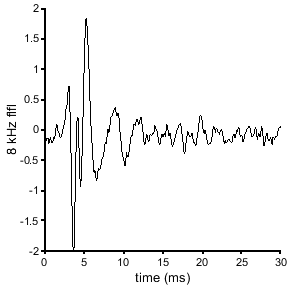


% Pure tones 
flfl8 ={1,2,3}; % 8kHz - 10 dB attenuation 
addpath('cjk-2019_09_12-P16_abr_cx26flfl_1');
flfl8{1,1} = EPavg_p023;
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_1')
addpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
flfl8{1,2} = EPavg_p042;
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
addpath('cjk-2019_10_08-P16_abr_cx26flfl_3');
flfl8{1,3} = EPavg_p031;
rmpath('cjk-2019_10_08-P16_abr_cx26flfl_3');


meanflfl8 = mean([(flfl8{1,1}.AverageData(:,4))';(flfl8{1,2}.AverageData(:,4))';(flfl8{1,3}.AverageData(:,4))'],1);
stdflfl8 = std([(flfl8{1,1}.AverageData(:,4))';(flfl8{1,2}.AverageData(:,4))';(flfl8{1,3}.AverageData(:,4))'],1);

figure
plot(flfl8{1,1}.AverageData(:,1)',meanflfl8,'k')
dim = [3 3];
xlim([0 30]);
xlabel('time (ms)');
ylabel('8 kHz flfl');
handle = gcf;
figQuality(gcf,gca,dim);

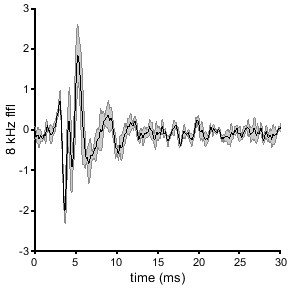

figure
shadedErrorBar(flfl8{1,1}.AverageData(:,1)',meanflfl8,stdflfl8)
dim = [3 3];
xlim([0 30]);
xlabel('time (ms)');
ylabel('8 kHz flfl');
handle = gcf;
figQuality(gcf,gca,dim);

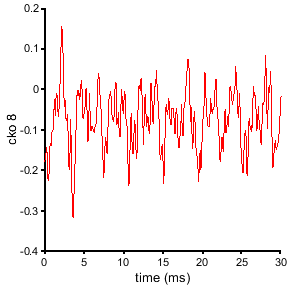


cko8 ={1,2,3,4};
addpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3');
cko8{1,1} = EPavg_p007;
rmpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3')
addpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
cko8{1,2} = EPavg_p011;
rmpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
cko8{1,3} = EPavg_p012;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
cko8{1,4} = EPavg_p027;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');

meancko8 = mean([(cko8{1,1}.AverageData(:,4))';(cko8{1,2}.AverageData(:,4))';(cko8{1,3}.AverageData(:,4))';(cko8{1,4}.AverageData(:,4))'],1);

plot(cko8{1,1}.AverageData(:,1)',meancko8,'r')
dim = [3 3];
xlim([0 30]);
%ylim([-6 6]);
xlabel('time (ms)');
ylabel('cko 8');
handle = gcf;
figQuality(gcf,gca,dim);

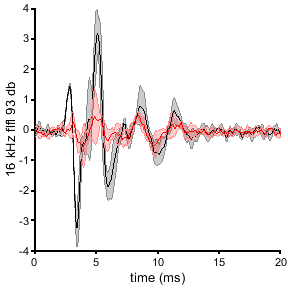


% 16 kHz 
flfl16 ={1,2,3}; % 16 kHz - 10 dB attenuation is 93
addpath('cjk-2019_09_12-P16_abr_cx26flfl_1');
flfl16{1,1} = EPavg_p042;
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_1')
addpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
flfl16{1,2} = EPavg_p012;
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
addpath('cjk-2019_10_08-P16_abr_cx26flfl_3');
flfl16{1,3} = EPavg_p011;
rmpath('cjk-2019_10_08-P16_abr_cx26flfl_3');

meanflfl16 = mean([(flfl16{1,1}.AverageData(:,4))';(flfl16{1,2}.AverageData(:,4))';(flfl16{1,3}.AverageData(:,4))'],1);
stdflfl16 = std([(flfl16{1,1}.AverageData(:,4))';(flfl16{1,2}.AverageData(:,4))';(flfl16{1,3}.AverageData(:,4))'],1);
figure
%plot(flfl16{1,1}.AverageData(:,1)',meanflfl16,'k','LineWidth',2)
hold on
shadedErrorBar(flfl16{1,1}.AverageData(:,1)',meanflfl16,stdflfl16)

cko16 ={1,2,3,4};
addpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3');
cko16{1,1} = EPavg_p011;
rmpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3')
addpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
cko16{1,2} = EPavg_p015;
rmpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
cko16{1,3} = EPavg_p016;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
cko16{1,4} = EPavg_p022;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
meancko16 = mean([(cko16{1,1}.AverageData(:,4))';(cko16{1,2}.AverageData(:,4))';(cko16{1,3}.AverageData(:,4))';(cko16{1,4}.AverageData(:,4))'],1);
stdcko16 = std([(cko16{1,1}.AverageData(:,4))';(cko16{1,2}.AverageData(:,4))';(cko16{1,3}.AverageData(:,4))';(cko16{1,4}.AverageData(:,4))'],1);
%plot(cko16{1,1}.AverageData(:,1)',meancko16,'r','LineWidth',2)
shadedErrorBar(cko16{1,1}.AverageData(:,1)',meancko16,stdcko16,'lineprops','r')
dim = [3 3];
xlim([0 20]);
xlabel('time (ms)');
ylabel('16 kHz flfl 93 db');
handle = gcf;
figQuality(gcf,gca,dim);
hold off

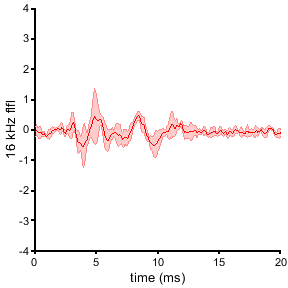


figure
shadedErrorBar(cko16{1,1}.AverageData(:,1)',meancko16,stdcko16,'lineprops','r')
dim = [3 3];
xlim([0 20]);
xlabel('time (ms)');
ylabel('16 kHz flfl');
ylim([-4 4])
handle = gcf;
figQuality(gcf,gca,dim);

% cko 16 kHz 0 db atten. 
cko16 ={1,2,3,4};
addpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3');
cko16{1,1} = EPavg_p010;
rmpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3')
addpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
cko16{1,2} = EPavg_p013;
rmpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
cko16{1,3} = EPavg_p015;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
cko16{1,4} = EPavg_p021;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
meancko16 = mean([(cko16{1,1}.AverageData(:,4))';(cko16{1,2}.AverageData(:,4))';(cko16{1,3}.AverageData(:,4))';(cko16{1,4}.AverageData(:,4))'],1);
stdcko16 = std([(cko16{1,1}.AverageData(:,4))';(cko16{1,2}.AverageData(:,4))';(cko16{1,3}.AverageData(:,4))';(cko16{1,4}.AverageData(:,4))'],1);
hold on

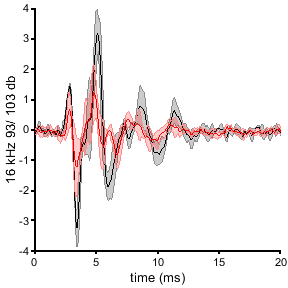

figure
shadedErrorBar(flfl16{1,1}.AverageData(:,1)',meanflfl16,stdflfl16)
shadedErrorBar(cko16{1,1}.AverageData(:,1)',meancko16,stdcko16,'lineprops','r')
dim = [3 3];
xlim([0 20]);
xlabel('time (ms)');
ylabel('16 kHz 93/ 103 db');
ylim([-4 4])
handle = gcf;
figQuality(gcf,gca,dim);

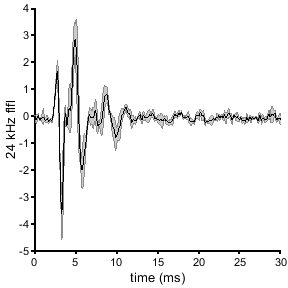


% 24 kHz - 10 dB atten
flfl24 ={1,2,3}; % 16 kHz - 10 dB attenuation is 93
addpath('cjk-2019_09_12-P16_abr_cx26flfl_1');
flfl24{1,1} = EPavg_p013;
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_1')
addpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
flfl24{1,2} = EPavg_p022;
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
addpath('cjk-2019_10_08-P16_abr_cx26flfl_3');
flfl24{1,3} = EPavg_p021;
rmpath('cjk-2019_10_08-P16_abr_cx26flfl_3');

meanflfl24 = mean([(flfl24{1,1}.AverageData(:,4))';(flfl24{1,2}.AverageData(:,4))';(flfl24{1,3}.AverageData(:,4))'],1);
stdflfl24 = std([(flfl24{1,1}.AverageData(:,4))';(flfl24{1,2}.AverageData(:,4))';(flfl24{1,3}.AverageData(:,4))'],1);
figure 
% plot(flfl24{1,1}.AverageData(:,1)',meanflfl24,'k')
shadedErrorBar(flfl24{1,1}.AverageData(:,1)',meanflfl24,stdflfl24)
dim = [3 3];
xlim([0 30]);
xlabel('time (ms)');
ylabel('24 kHz flfl');
handle = gcf;
figQuality(gcf,gca,dim);

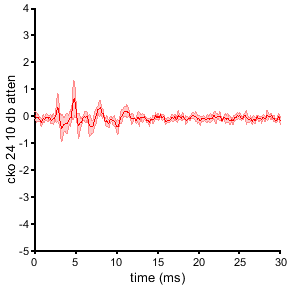


cko24 ={1,2,3,4};
addpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3');
cko24{1,1} = EPavg_p015;
rmpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3')
addpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
cko24{1,2} = EPavg_p019;
rmpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
cko24{1,3} = EPavg_p020;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
cko24{1,4} = EPavg_p016;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
meancko24 = mean([(cko24{1,1}.AverageData(:,4))';(cko24{1,2}.AverageData(:,4))';(cko24{1,3}.AverageData(:,4))';(cko24{1,4}.AverageData(:,4))'],1);
stdcko24 = std([(cko24{1,1}.AverageData(:,4))';(cko24{1,2}.AverageData(:,4))';(cko24{1,3}.AverageData(:,4))';(cko24{1,4}.AverageData(:,4))'],1);
%plot(cko24{1,1}.AverageData(:,1)',meancko24,'r')
figure
shadedErrorBar(cko24{1,1}.AverageData(:,1)',meancko24,stdcko24,'lineprops','r')
dim = [3 3];
xlim([0 30]);
ylim([-5 4]);
xlabel('time (ms)');
ylabel('cko 24 10 db atten');
handle = gcf;
figQuality(gcf,gca,dim);

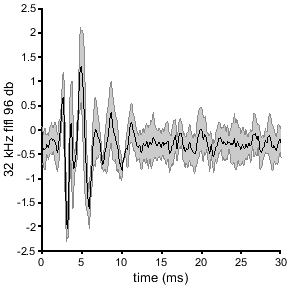


% 32 kHz
flfl32 ={1,2,3}; % 16 kHz - 10 dB attenuation is 93
addpath('cjk-2019_09_12-P16_abr_cx26flfl_1');
flfl32{1,1} = EPavg_p032;
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_1')
addpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
flfl32{1,2} = EPavg_p032;
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
addpath('cjk-2019_10_08-P16_abr_cx26flfl_3');
flfl32{1,3} = EPavg_p039;
rmpath('cjk-2019_10_08-P16_abr_cx26flfl_3');

meanflfl32 = mean([(flfl32{1,1}.AverageData(:,4))';(flfl32{1,2}.AverageData(:,4))';(flfl32{1,3}.AverageData(:,4))'],1);
stdflfl32 = std([(flfl32{1,1}.AverageData(:,4))';(flfl32{1,2}.AverageData(:,4))';(flfl32{1,3}.AverageData(:,4))'],1);
%plot(flfl32{1,1}.AverageData(:,1)',meanflfl32,'k')
figure
shadedErrorBar(flfl32{1,1}.AverageData(:,1)',meanflfl32,stdflfl32)
dim = [3 3];
xlim([0 30]);
xlabel('time (ms)');
ylabel('32 kHz flfl 96 db');
handle = gcf;
figQuality(gcf,gca,dim);

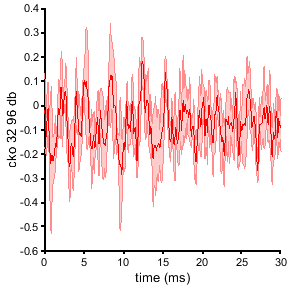


cko32 ={1,2,3,4};
addpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3');
cko32{1,1} = EPavg_p022;
rmpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3')
addpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
cko32{1,2} = EPavg_p023;
rmpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
cko32{1,3} = EPavg_p026;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
cko32{1,4} = EPavg_p012;
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
meancko32 = mean([(cko32{1,1}.AverageData(:,4))';(cko32{1,2}.AverageData(:,4))';(cko32{1,3}.AverageData(:,4))';(cko32{1,4}.AverageData(:,4))'],1);
stdcko32 = std([(cko32{1,1}.AverageData(:,4))';(cko32{1,2}.AverageData(:,4))';(cko32{1,3}.AverageData(:,4))';(cko32{1,4}.AverageData(:,4))'],1);
%plot(cko32{1,1}.AverageData(:,1)',meancko32,'r')
figure
shadedErrorBar(cko32{1,1}.AverageData(:,1)',meancko32,stdcko32,'lineprops','r')

dim = [3 3];
xlim([0 30]);
%ylim([-6 6]);
xlabel('time (ms)');
ylabel('cko 32 96 db');
handle = gcf;
figQuality(gcf,gca,dim);

% 16 kHz mean waterfall plot
% controls : flfl

addpath('cjk-2019_09_12-P16_abr_cx26flfl_1');
flfl1 ={EPavg_p042,EPavg_p043,EPavg_p044,EPavg_p045,EPavg_p046};
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_1');
addpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
flfl2 ={EPavg_p012,EPavg_p013,EPavg_p014,EPavg_p015,EPavg_p016};
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
addpath('cjk-2019_10_08-P16_abr_cx26flfl_3');
flfl3 ={EPavg_p011,EPavg_p012,EPavg_p013,EPavg_p014,EPavg_p015};
rmpath('cjk-2019_10_08-P16_abr_cx26flfl_3');

meanflfl10 = mean([(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))'],1);
meanflfl20 = mean([(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))'],1);
meanflfl30 = mean([(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))'],1);
meanflfl40 = mean([(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))'],1);
meanflfl50 = mean([(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))'],1);

flflmean = {meanflfl10,meanflfl20,meanflfl30,meanflfl40,meanflfl50}

flflmean = 1×5 cell array
    {1×293 double}    {1×293 double}    {1×293 double}    {1×293 double}    {1×293 double}



stdflfl10 = std([(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))'],1);
stdflfl20 = std([(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))'],1);
stdflfl30 = std([(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))'],1);
stdflfl40 = std([(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))'],1);
stdflfl50 = std([(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))'],1);

flflstd = {stdflfl10,stdflfl20,stdflfl30,stdflfl40,stdflfl50}

flflstd = 1×5 cell array
    {1×293 double}    {1×293 double}    {1×293 double}    {1×293 double}    {1×293 double}


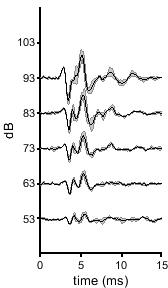


% plot in waterfall

figure
hold on
for x = 1:length(flflmean)
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-5*(x-1),flflstd{1,x})
end
dim =[1.75,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([-20 -15 -10 -5 0 5]);
yticklabels([53 63 73 83 93 103])
ylim([-25 10])
hold off

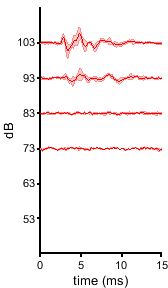


% cKO 16 kHz 
addpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3');
cko1 ={EPavg_p010,EPavg_p011,EPavg_p012,EPavg_p014};
rmpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3');
addpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
cko2 ={EPavg_p013,EPavg_p015,EPavg_p017};
rmpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
cko3 ={EPavg_p015,EPavg_p016,EPavg_p017};
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
cko4 ={EPavg_p021,EPavg_p022,EPavg_p023,EPavg_p025};
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');

meancko0 = mean([(cko1{1,1}.AverageData(:,4))';(cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))'],1);
meancko10 = mean([(cko1{1,2}.AverageData(:,4))';(cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))'],1);
meancko20 = mean([(cko1{1,3}.AverageData(:,4))';(cko2{1,3}.AverageData(:,4))';(cko3{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))'],1);
meancko30 = mean([(cko1{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))'],1);

ckomean = {meancko0,meancko10,meancko20,meancko30};
stdcko0 = std([(cko1{1,1}.AverageData(:,4))';(cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))'],1);
stdcko10 = std([(cko1{1,2}.AverageData(:,4))';(cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))'],1);
stdcko20 = std([(cko1{1,3}.AverageData(:,4))';(cko2{1,3}.AverageData(:,4))';(cko3{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))'],1);
stdcko30 = std([(cko1{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))'],1);
stdcko = {stdcko0,stdcko10,stdcko20,stdcko30};
figure
hold on
for x = 1:length(ckomean)
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(cko1{1,1}.AverageData(:,1),ckomean{1,x}-5*(x-2),stdcko{1,x},'lineprops','r')
end
dim =[1.75,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([-20 -15 -10 -5 0 5]);
yticklabels([53 63 73 83 93 103])
ylim([-25 10])
hold off

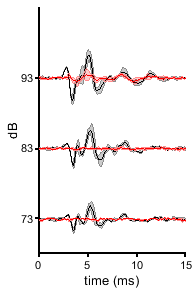


ckomean = {meancko10,meancko20,meancko30};
stdcko = {stdcko10,stdcko20,stdcko30};
% combined plot
figure
hold on
for x = 1:3
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),flflstd{1,x})
end
for x = 1:3
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(cko1{1,1}.AverageData(:,1),ckomean{1,x}-10*(x-1),stdcko{1,x},'lineprops','r')
end
dim =[2,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([-20 -10 0]);
yticklabels([73 83 93])
ylim([-25 10])
hold off
print(gcf,'-dpdf')

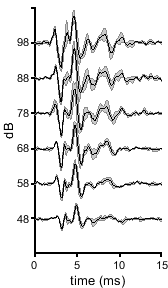

% click waterfall plots
addpath('cjk-2019_09_12-P16_abr_cx26flfl_1');
flfl1 ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_1');
addpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
flfl2 ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_09_12-P16_abr_cx26flfl_2');
addpath('cjk-2019_10_08-P16_abr_cx26flfl_3');
flfl3 ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_10_08-P16_abr_cx26flfl_3');

meanflfl10 = mean([(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))'],1);
meanflfl20 = mean([(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))'],1);
meanflfl30 = mean([(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))'],1);
meanflfl40 = mean([(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))'],1);
meanflfl50 = mean([(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))'],1);
meanflfl60 = mean([(flfl1{1,6}.AverageData(:,4))';(flfl2{1,6}.AverageData(:,4))';(flfl3{1,6}.AverageData(:,4))'],1);

flflmean = {meanflfl10,meanflfl20,meanflfl30,meanflfl40,meanflfl50,meanflfl60};

stdflfl10 = std([(flfl1{1,1}.AverageData(:,4))';(flfl2{1,1}.AverageData(:,4))';(flfl3{1,1}.AverageData(:,4))'],1);
stdflfl20 = std([(flfl1{1,2}.AverageData(:,4))';(flfl2{1,2}.AverageData(:,4))';(flfl3{1,2}.AverageData(:,4))'],1);
stdflfl30 = std([(flfl1{1,3}.AverageData(:,4))';(flfl2{1,3}.AverageData(:,4))';(flfl3{1,3}.AverageData(:,4))'],1);
stdflfl40 = std([(flfl1{1,4}.AverageData(:,4))';(flfl2{1,4}.AverageData(:,4))';(flfl3{1,4}.AverageData(:,4))'],1);
stdflfl50 = std([(flfl1{1,5}.AverageData(:,4))';(flfl2{1,5}.AverageData(:,4))';(flfl3{1,5}.AverageData(:,4))'],1);
stdflfl60 = std([(flfl1{1,6}.AverageData(:,4))';(flfl2{1,6}.AverageData(:,4))';(flfl3{1,6}.AverageData(:,4))'],1);

flflstd = {stdflfl10,stdflfl20,stdflfl30,stdflfl40,stdflfl50,stdflfl60};

% plot in waterfall

figure
hold on
for x = 1:length(flflmean)
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-5*(x-1),flflstd{1,x})
end
dim =[1.75,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([-25 -20 -15 -10 -5 0 5]);
yticklabels([48 58 68 78 88 98])
ylim([-30 5])
hold off

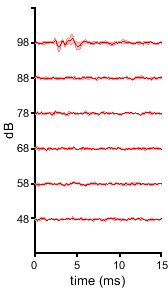


% cko click waterfall
addpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3');
cko1 ={EPavg_p003,EPavg_p002};
rmpath('cjk-2019_09_12-P16_abr_tectacx26flfl_3');
addpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
cko2 ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_09_20-P15_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
cko3 ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_1');
addpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');
cko4 ={EPavg_p003,EPavg_p002,EPavg_p004,EPavg_p005,EPavg_p006,EPavg_p007};
rmpath('cjk-2019_10_08-P16_abr_tectacx26flfl_4');

meancko0 = mean([(cko1{1,1}.AverageData(:,4))';(cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))'],1);
meancko10 = mean([(cko1{1,2}.AverageData(:,4))';(cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))'],1);
meancko20 = mean([(cko2{1,3}.AverageData(:,4))';(cko3{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))'],1);
meancko30 = mean([(cko2{1,4}.AverageData(:,4))';(cko3{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))'],1);
meancko40 = mean([(cko2{1,5}.AverageData(:,4))';(cko3{1,5}.AverageData(:,4))';(cko4{1,5}.AverageData(:,4))'],1);
meancko50 = mean([(cko2{1,6}.AverageData(:,4))';(cko3{1,6}.AverageData(:,4))';(cko4{1,6}.AverageData(:,4))'],1);

ckomean = {meancko0,meancko10,meancko20,meancko30,meancko40,meancko50};
stdcko0 = std([(cko1{1,1}.AverageData(:,4))';(cko2{1,1}.AverageData(:,4))';(cko3{1,1}.AverageData(:,4))';(cko4{1,1}.AverageData(:,4))'],1);
stdcko10 = std([(cko1{1,2}.AverageData(:,4))';(cko2{1,2}.AverageData(:,4))';(cko3{1,2}.AverageData(:,4))';(cko4{1,2}.AverageData(:,4))'],1);
stdcko20 = std([(cko2{1,3}.AverageData(:,4))';(cko3{1,3}.AverageData(:,4))';(cko4{1,3}.AverageData(:,4))'],1);
stdcko30 = std([(cko2{1,4}.AverageData(:,4))';(cko3{1,4}.AverageData(:,4))';(cko4{1,4}.AverageData(:,4))'],1);
stdcko40 = std([(cko2{1,5}.AverageData(:,4))';(cko3{1,5}.AverageData(:,4))';(cko4{1,5}.AverageData(:,4))'],1);
stdcko50 = std([(cko2{1,6}.AverageData(:,4))';(cko3{1,6}.AverageData(:,4))';(cko4{1,6}.AverageData(:,4))'],1);

stdcko = {stdcko0,stdcko10,stdcko20,stdcko30,stdcko40,stdcko50};

figure
hold on
for x = 1:length(ckomean)
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(cko1{1,1}.AverageData(:,1),ckomean{1,x}-5*(x-1),stdcko{1,x},'lineprops','r')
end
dim =[1.75,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([-25 -20 -15 -10 -5 0 5]);
yticklabels([48 58 68 78 88 98])
ylim([-30 5])
hold off

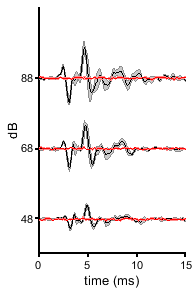


% combined 

figure
hold on
for x = 2:2:6
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-5*(x-2),flflstd{1,x})
end
for x = 2:2:6
    %plot(flfl1{1,1}.AverageData(:,1),flflmean{1,x}-10*(x-1),'k','LineWidth',1.5)
    shadedErrorBar(cko1{1,1}.AverageData(:,1),ckomean{1,x}-5*(x-2),stdcko{1,x},'lineprops','r')
end
dim =[2,3];
xlim([0 15]);
xlabel('time (ms)');
ylabel('dB');
handle = gcf;
figQuality(gcf,gca,dim);
yticks([-20 -10 0]);
yticklabels([48 68 88])
ylim([-25 10])
hold off
print(gcf,'-dpdf')